% Header

# Phase Diagram

The below figure is a phase diagram for a copper-nickel alloy.  Write the MATLAB program to do the following tasks:

- Re-create the below figure including all phase division lines, phase names, axis labels and chart title.

- Ask the user to enter a two element vector of percent nickel and temperature at the Command Window. (You may assume the user will enter a properly formatted two-element vector, i.e., no data validation needed.)

- The program will plot the point entered by the user with a symbol as defined in the variable **iSym.**

- The program will output a formatted statement to the Command Window, similar to“`For m % Nickel at T `*°*`C, ``the phase is ``Phase`,” where `w`, `T, `and `Phase `are replaced by the actual values. Format the values of `w `and `T `as integer values. 

#### Test cases [percent nickel, temperature]:

- [50, 1350]

- [55, 1300]

- [45, 1250]

- [50, 1325]

- [60, 1150]

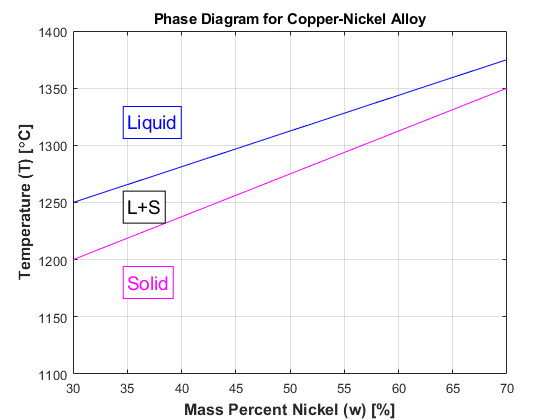

% Housekeeping
clear
close all
clc

% Alloy Phases and plotting options
Phases = {'Liquid','L+S','Solid'};
iSym = {'bV';'ko';'mx'};

% Basic graph
figure('Color','w')
plot([30 70], [1250 1375],'-b')
hold on
plot([30 70], [1200 1350], '-m')
axis([30 70 1100 1400])
grid on

% Axis Labels & Plot Title
xlabel('Mass Percent Nickel (w) [%]', "FontSize",12,"FontWeight","bold")
ylabel('Temperature (T) [\circC]', "FontSize",12,"FontWeight","bold")
title('Phase Diagram for Copper-Nickel Alloy')

% Graph annotations
text(35,1320,Phases{1},"BackgroundColor",'w','Color','b',"FontSize",14,'EdgeColor','b')
text(35,1246,Phases{2},"BackgroundColor",'w','Color','k',"FontSize",14,'EdgeColor','k')
text(35,1180,Phases{3},"BackgroundColor",'w','Color','m',"FontSize",14,'EdgeColor','m')

% Ask User to Enter Nickel Content (W) and Temperature (T)
numbers={'enter nickle content','enter temperature'};
Inputs=inputdlg(numbers)

Inputs = 2×1 cell array
    {'4'}
    {'4'}


W=str2num(Inputs{1})

W = 4

T=str2num(Inputs{2})

T = 4

% The program will plot the point entered by the user with a symbol as defined in the variable iSym.
hold on;
m=randi(length(iSym))

m = 1

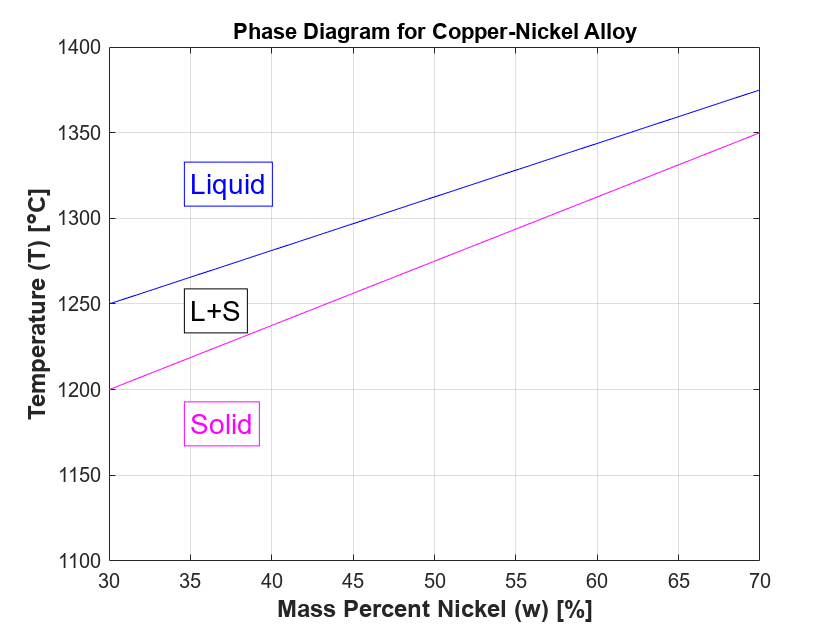

plot(W,T,iSym{m},'Markersize',10)


% Theorectical line for solid
w=[30 70]

w =     30    70


T1=[1200 1350]

T1 =         1200        1350


B1=polyfit(w,T1,1)

B1 = 1.0e+03 *

    0.0038    1.0875


m1=B1(1)

m1 = 3.7500

b1=B1(2)

b1 = 1.0875e+03


% Theorectical line for liquid
w=[30 70]

w =     30    70


T2=[1250 1375]

T2 =         1250        1375


B2=polyfit(w,T2,1)

B2 = 1.0e+03 *

    0.0031    1.1562


m2=B2(1)

m2 = 3.1250

b2=B2(2)

b2 = 1.1563e+03


T_1=m1*w+b1

T_1 = 1.0e+03 *

    1.2000    1.3500


T_2=m2*w+b2

T_2 = 1.0e+03 *

    1.2500    1.3750



% Classification Analysis
if T<=T_1
    Phase='Solid'
elseif T>T_2
    Phase='Liquid'
else
    Phase='L+S'
end

Phase = 'Solid'


% The program will output a formatted statement to the Command Window
fprintf('For %0.0f %% Nickle at %0.0f %cC, the phase is %s',W,T,char(176),Phase)

For 4 % Nickle at 4 °C, the phase is Solid